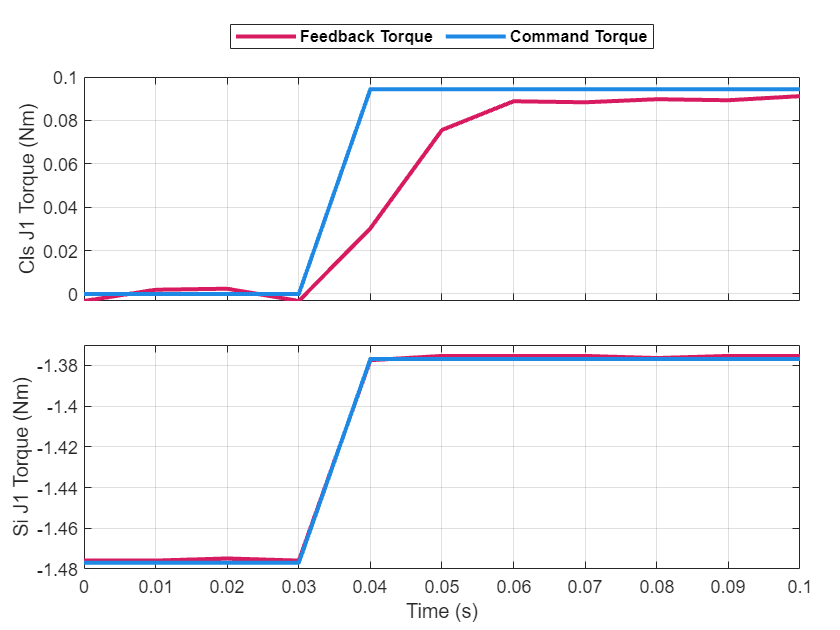

clc;
clear;

fb_si_data = readmatrix('../exp_dec_29_transient_si/data/joints/free_train_0.csv');
cmd_si_data = readmatrix('../exp_dec_29_transient_si/data/setpoint/free_train_0.csv');
fb_cls_data = readmatrix('../exp_jan_1_transient_cls/data/joints/free_train_0.csv');
cmd_cls_data = readmatrix('../exp_jan_1_transient_cls/data/setpoint/free_train_0.csv');

figure()
tcl = tiledlayout(2,1, 'TileSpacing','Compact','Padding','Compact');

% title(tcl, sprintf('dVRK Classic and dVRK-Si Joint 1 \n Torque Transient Performance: Feedback vs. Command'), fontweight='Bold')


currentST_si = 6.2/0.01;
currentET_si = 6.3/0.01;
currentST_cls = 3.26/0.01;
currentET_cls = 3.36/0.01;
% currentST_si = 1/0.01;
% currentET_si = 9/0.01;
% currentST_cls = 1/0.01;
% currentET_cls = 6/0.01;

nexttile
plot(0.01*(1-1:length(fb_cls_data(currentST_cls:currentET_cls,2))-1), fb_cls_data(currentST_cls:currentET_cls,14), color = '#D81B60', LineWidth=2)
hold on
% title(sprintf('Fy, RMSE = %.4f', loss_y))
plot(0.01*(1-1:length(cmd_cls_data(currentST_cls:currentET_cls,2))-1), cmd_cls_data(currentST_cls:currentET_cls,14), color ='#1E88E5', LineWidth=2)
xticklabels([])
% xlabel('Time (s)')
ylabel('Cls J1 Torque (Nm)')
grid on
hold off
legend('Feedback Torque', 'Command Torque', Location='northoutside', fontweight='Bold', Orientation='horizon')

nexttile
plot(0.01*(1-1:length(fb_si_data(currentST_si:currentET_si,1))-1), fb_si_data(currentST_si:currentET_si,14), color = '#D81B60', LineWidth=2)
hold on
% title(sprintf('Fx, RMSE = %.4f', loss_x))
plot(0.01*(1-1:length(cmd_si_data(currentST_si:currentET_si,1))-1), cmd_si_data(currentST_si:currentET_si,14), color ='#1E88E5', LineWidth=2)
xlim tight
ylim tight
ylim([-1.48 -1.37])

xlabel('Time (s)')
ylabel('Si J1 Torque (Nm)')
grid on
hold off

figure(2)
tcl = tiledlayout(2,1, 'TileSpacing','Compact','Padding','Compact');

% title(tcl, sprintf('dVRK Classic and dVRK-Si Joint 1 \n PID Position Loop Performance: Feedback vs. Command'), fontweight='Bold')


pidST_si = 8.12/0.01;
pidET_si = 8.52/0.01;
pidST_cls = 5.18/0.01;
pidET_cls = 5.58/0.01;

nexttile
plot(0.01*(1-1:length(fb_cls_data(pidST_cls:pidET_cls,2))-1), fb_cls_data(pidST_cls:pidET_cls,14), color = '#D81B60', LineWidth=2)
hold on
% title(sprintf('Fy, RMSE = %.4f', loss_y))
plot(0.01*(1-1:length(cmd_cls_data(pidST_cls:pidET_cls,2))-1), cmd_cls_data(pidST_cls:pidET_cls,14), color ='#1E88E5', LineWidth=2)
xticks(0:0.05:0.7)
xticklabels([])
% xlabel('Time (s)')
ylim([-0.75 0.75])
ylabel('Cls J1 Torque (Nm)')
grid on
hold off
legend('Feedback Torque', 'Command Torque', Location='northoutside', fontweight='Bold', Orientation='horizon')

nexttile
plot(0.01*(1-1:length(fb_si_data(pidST_si:pidET_si,1))-1), fb_si_data(pidST_si:pidET_si,14), color = '#D81B60', LineWidth=2)

hold on
% title(sprintf('Fx, RMSE = %.4f', loss_x))
plot(0.01*(1-1:length(cmd_si_data(pidST_si:pidET_si,1))-1), cmd_si_data(pidST_si:pidET_si,14), color ='#1E88E5', LineWidth=2)

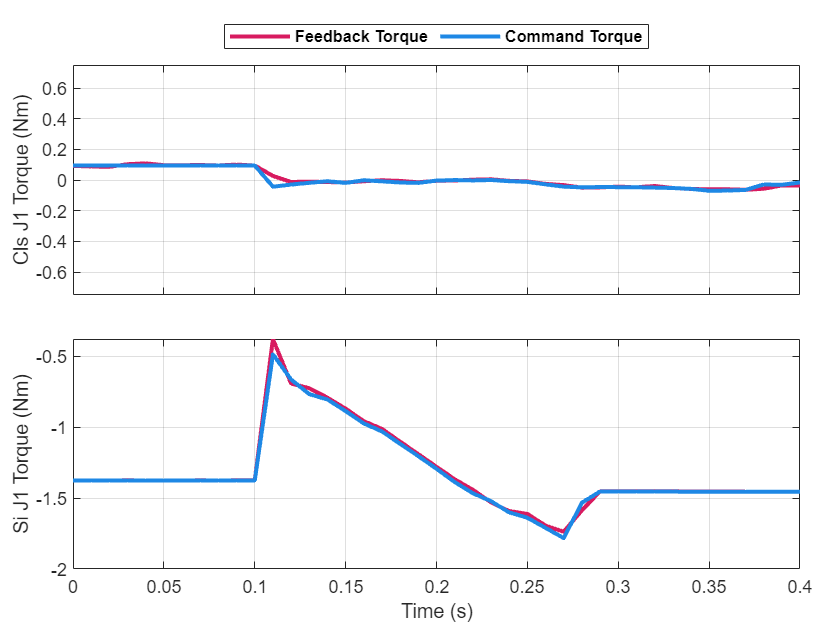

xlim tight
xticks(0:0.05:0.7)
% ylim([-1.48 -1.37])

xlabel('Time (s)')
ylabel('Si J1 Torque (Nm)')
grid on
hold off